1. e 2. Crie uma estrutura de dados (por exemplo, uma tabela) e guarde as seguintes informações relativas a cada áudio: a. diretório do áudio; b. nome do ficheiro (com extensão); c. participante; d. dígito; e. número da repetição. Desenvolva código para importação dos sinais de áudio e guarde o valor da taxa de amostragem e os sinais na estrutura de dados criada.

pastaAudios = '33';  
audios = dir(fullfile(pastaAudios, '*.wav'));

tabelaDados = table('Size', [0 7], ...
    'VariableTypes', {'string','string','string','double','double','double','double'}, ...
    'VariableNames', {'diretorio','nomeFicheiro','participante','digito','repeticao','sinal','taxaAmostragem'});

for i = 1:length(audios)
    nomeFicheiro = audios(i).name;
    diretorio = fullfile(pastaAudios, nomeFicheiro);
    
    partesNome = split(nomeFicheiro, '_'); 
    
    digito = str2double(partesNome{1});      
    participante = partesNome{2};  
    
    partesRepeticao = split(partesNome{3}, '.');  
    repeticao = str2double(partesRepeticao{1});
    
    [sinal, taxaAmostragem] = audioread(diretorio);

    novaEntrada = {diretorio, nomeFicheiro, participante, digito, repeticao, sinal, taxaAmostragem};
    tabelaDados = [tabelaDados; novaEntrada];
end

disp(tabelaDados);

       diretorio        nomeFicheiro     participante    digito    repeticao         sinal          taxaAmostragem
    ________________    _____________    ____________    ______    _________    ________________    ______________

    "33\0_33_0.wav"     "0_33_0.wav"         "33"          0           0        {33565×1 double}        48000     
    "33\0_33_1.wav"     "0_33_1.wav"         "33"          0           1        {26896×1 double}        48000     
    "33\0_33_10.wav"    "0_33_10.wav"        "33"          0          10        {33524×1 double}        48000     
    "33\0_33_11.wav"    "0_33_11.wav"        "33"          0          11        {32539×1 double}        48000     
    "33\0_33_12.wav"    "0_33_12.wav"        "33"          0          1

3. Reproduza e represente graficamente um exemplo dos sinais importados, identificando o dígito e o número da repetição a que cada um corresponde, e indicando o eixo horizontal com o tempo em segundos.

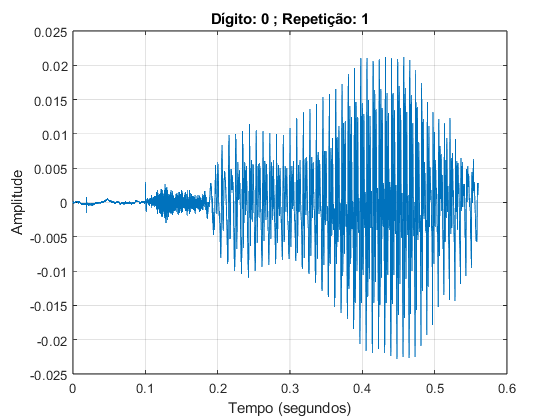

i = input('Linha: '); 

audio = tabelaDados(i, :);
digito = audio.digito;  
repeticao = audio.repeticao;  
sinal = audio.sinal{1};  
taxaAmostragem = audio.taxaAmostragem;  

tempo = (0:length(sinal)-1) / taxaAmostragem;

plot(tempo, sinal);
xlabel('Tempo (segundos)');
ylabel('Amplitude');
title(['Dígito: ', num2str(digito), ' ; Repetição: ', num2str(repeticao)]), grid on;